clc;
clear;
% Make sure the file name and path are correct
fullpath = 'C:\Users\rakyn\OneDrive\Desktop\TERM6\MISP_LAB\EEG_sig.mat';
load(fullpath)

**Q1:**

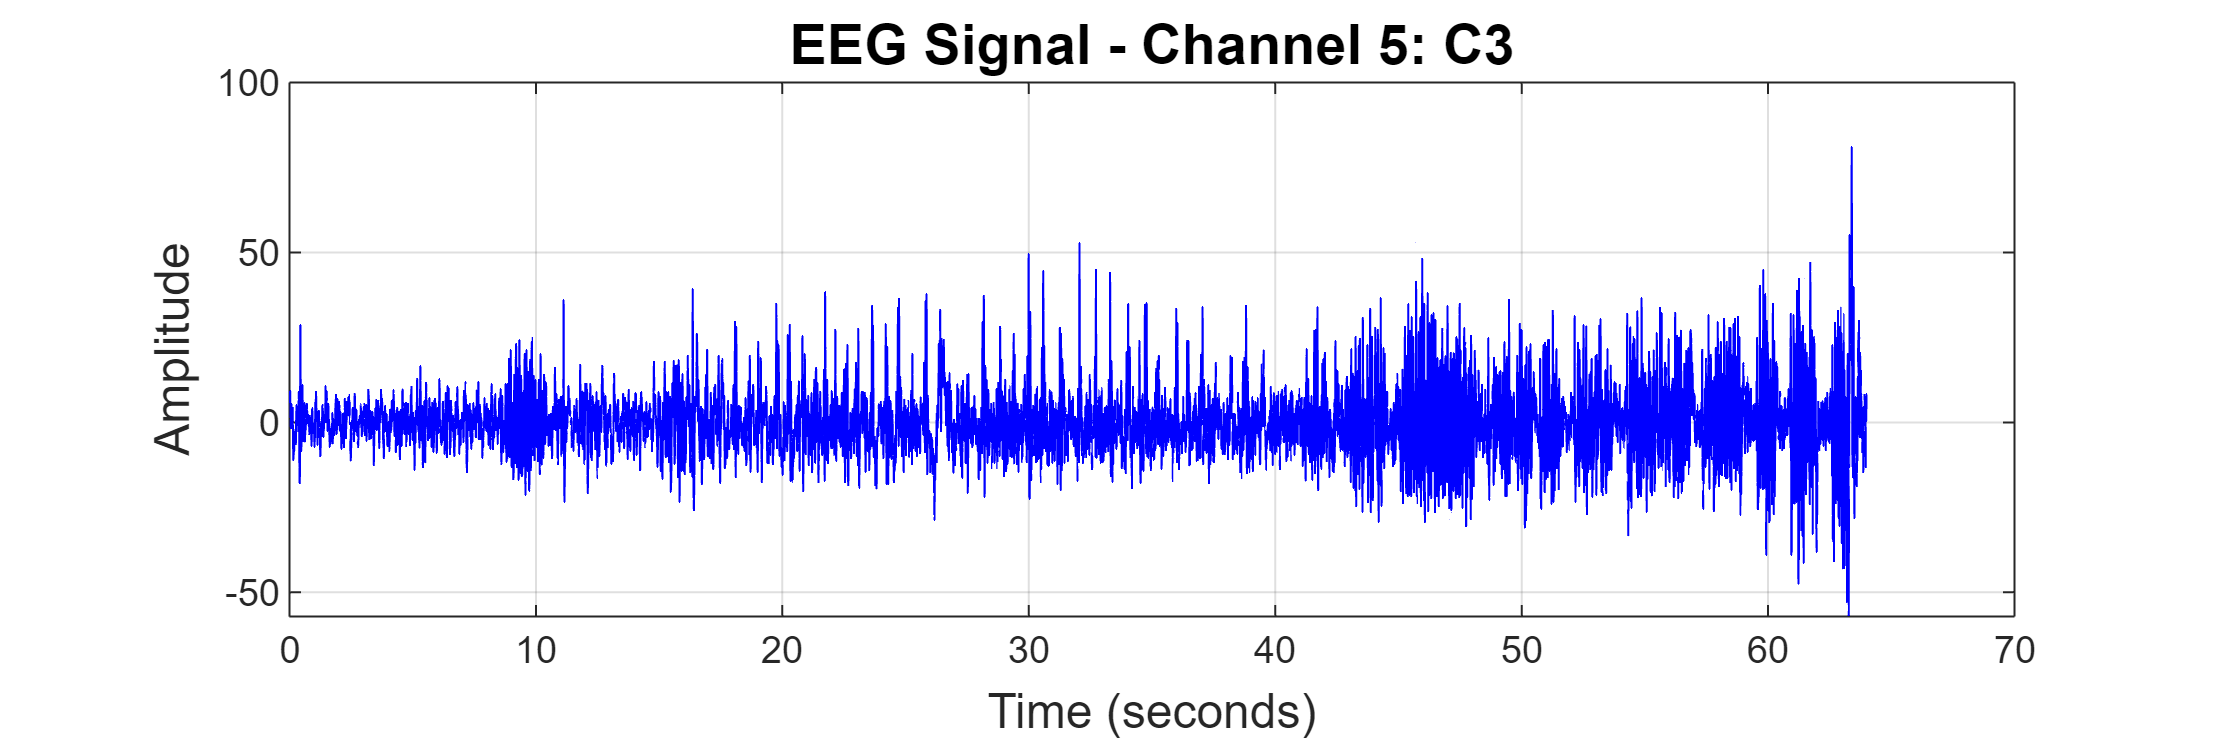

%%
fs = des.samplingfreq; 
ch_names = des.channelnames;  

% The 5th channel is typically C3 
ch5_data = Z(5, :);

%createing time vector
num_samples=length(ch5_data);
time=(0: num_samples-1)/fs ; %time in seconds

% Plot the 5th channel
figure('Position', [100, 100, 1200, 400]); 
plot(time, ch5_data, 'b-', 'LineWidth', 0.5);
xlabel('Time (seconds)', 'FontSize', 12);
ylabel('Amplitude', 'FontSize', 12);
title(sprintf('EEG Signal - Channel %d: %s', 5, ch_names{5}), 'FontSize', 14);
grid on;

**Q2:**

- **first 15ms :** Normal brain activity before any seizure onset, patient likely awake but resting.(Baseline activity with relatively low amplitude (approximately 10-30 units)and also the frequency is low

- **18 to 40ms:  **Beginning of seizure (ictal),sharp peaks reaching 60_80  and spiking pattern begins but frequnecy becomes more regular then previous part.

- **45 to 50 ms: ** Fast rhythmic activity phase.

- **last 50 ms: **Slower, irregular waves and amplitude becomes more variable ,also Less organized pattern than previous phases.Slower irregular activity phase

**Q3:**

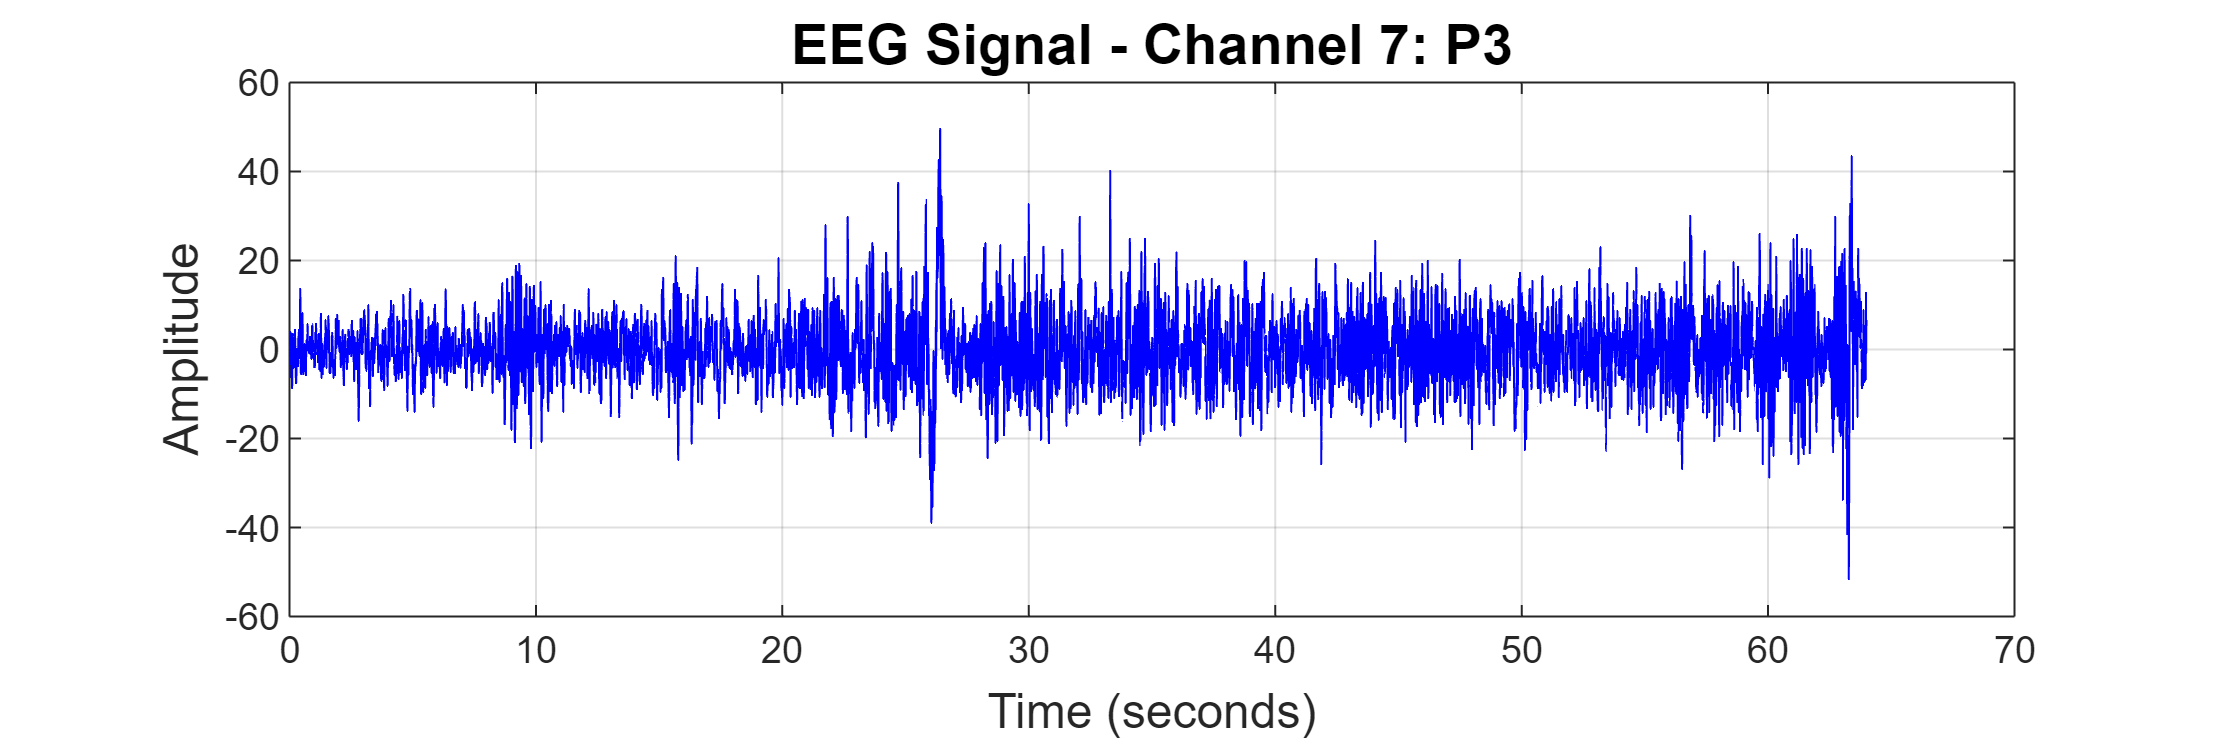

%%
ch7_data = Z(7, :);
% Plot the 7th channel
figure('Position', [100, 100, 1200, 400]); 
plot(time, ch7_data, 'b-', 'LineWidth', 0.5);
xlabel('Time (seconds)', 'FontSize', 12);
ylabel('Amplitude', 'FontSize', 12);
title(sprintf('EEG Signal - Channel %d: %s', 7, ch_names{7}), 'FontSize', 14);
grid on;

**Q4:**

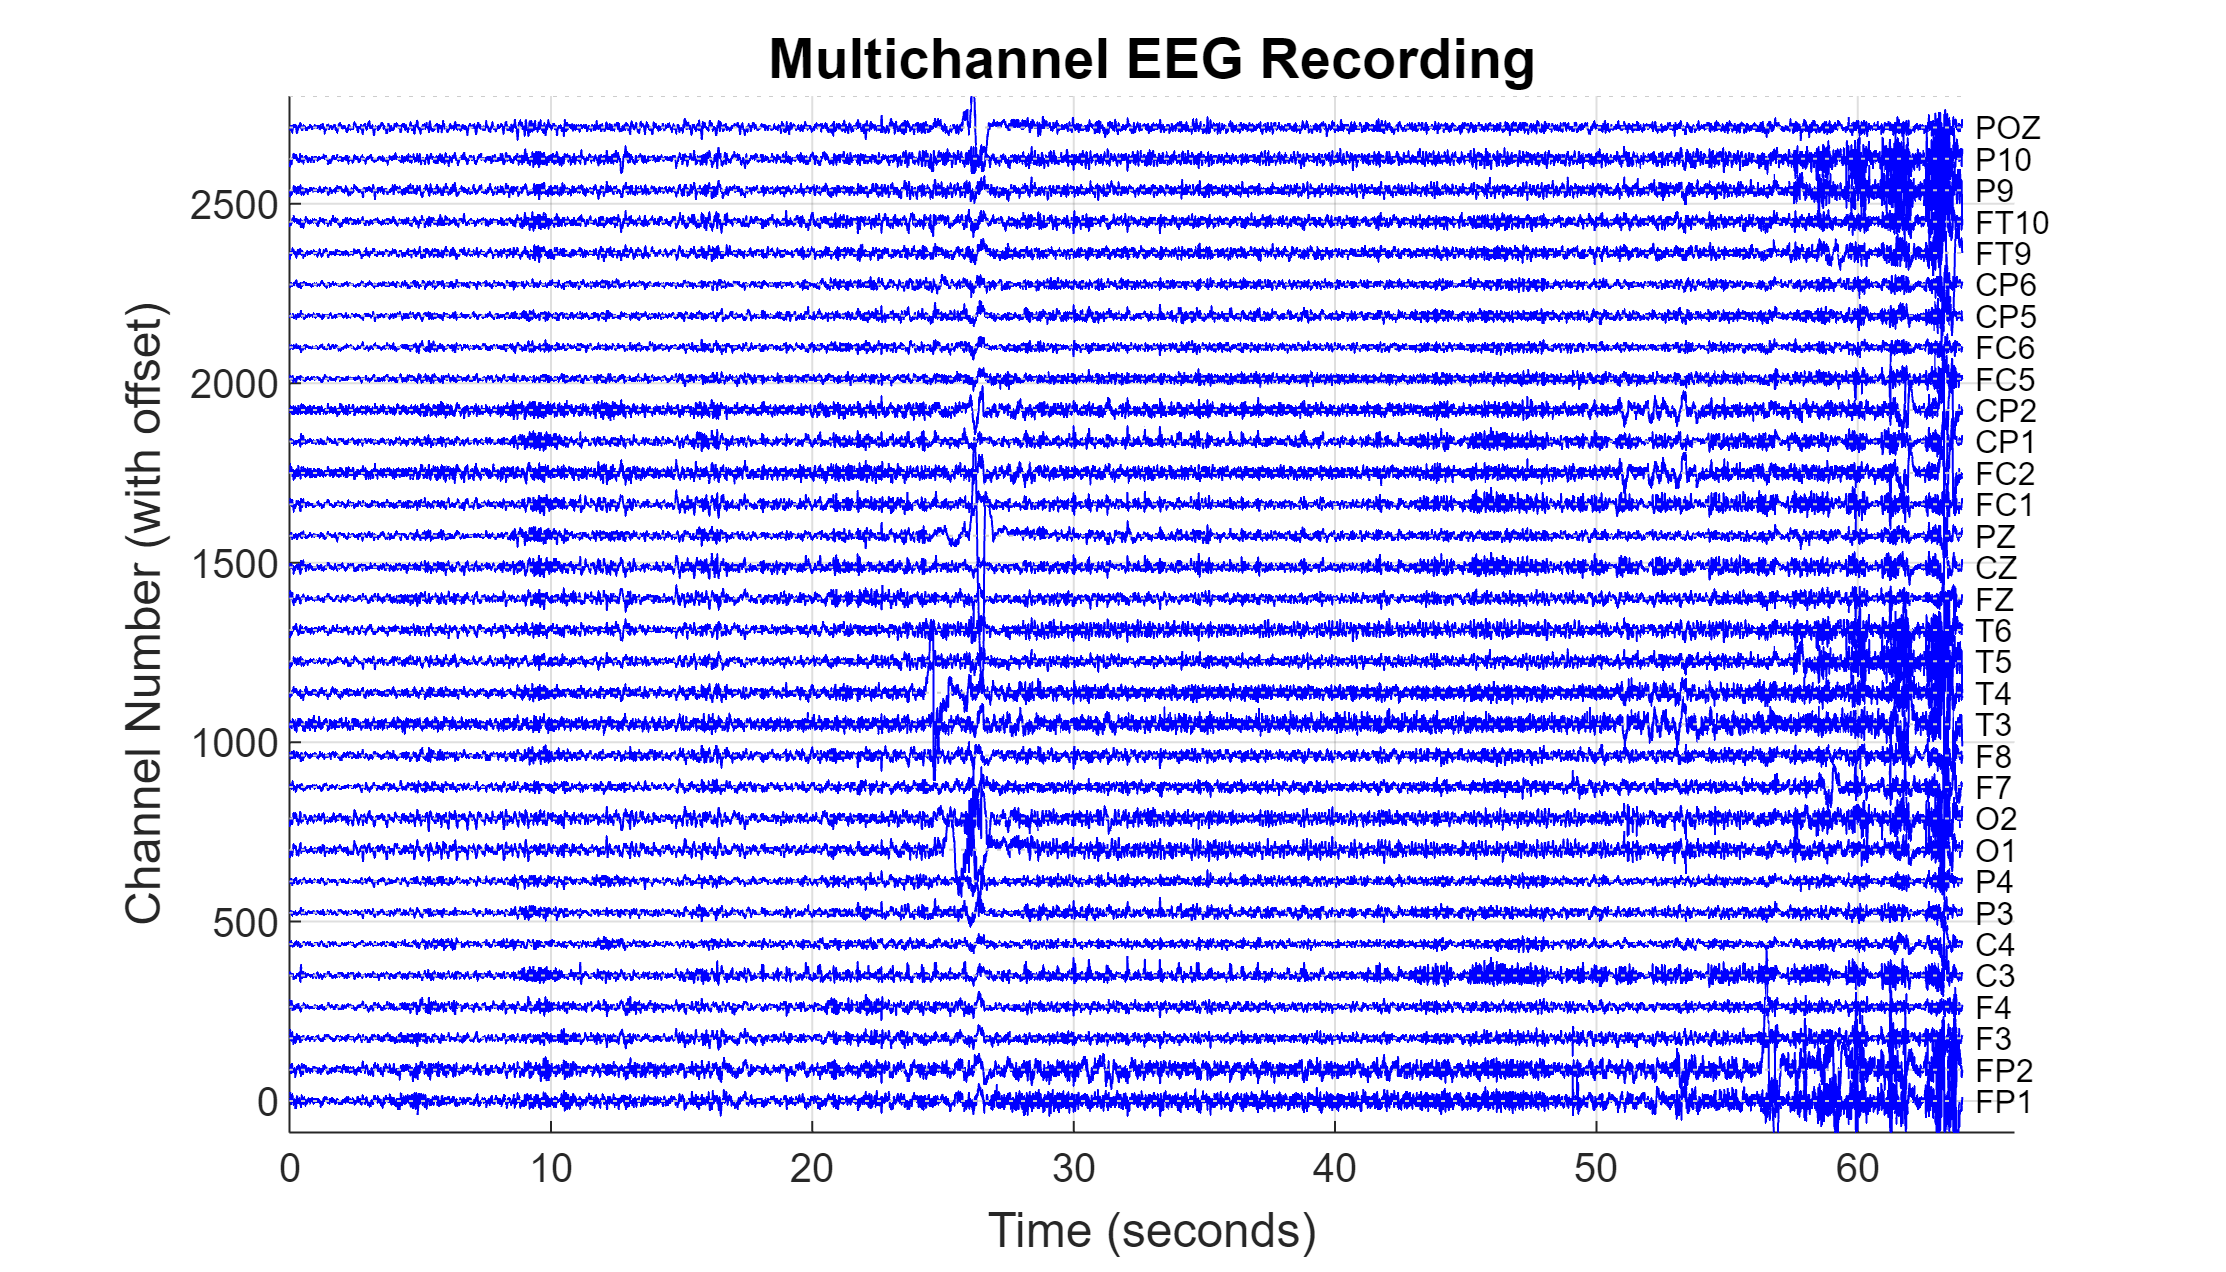

%% Calculate offset (vertical spacing between channels)
offset = max(max(abs(Z))) / 5;

ElecName = des.channelnames;

% Call the disp_eeg function
disp_eeg(Z, offset, fs, ElecName);

Channel C3 (located at the central region) shows the clearest seizure activity including rhythmic spikes, fast activity, and slow waves. Other channels, especially those far from the focus , show much weaker or no seizure activity.** This confirms that C3 is the optimal channel for detecting this patient's seizure activity.**

**Q6:**

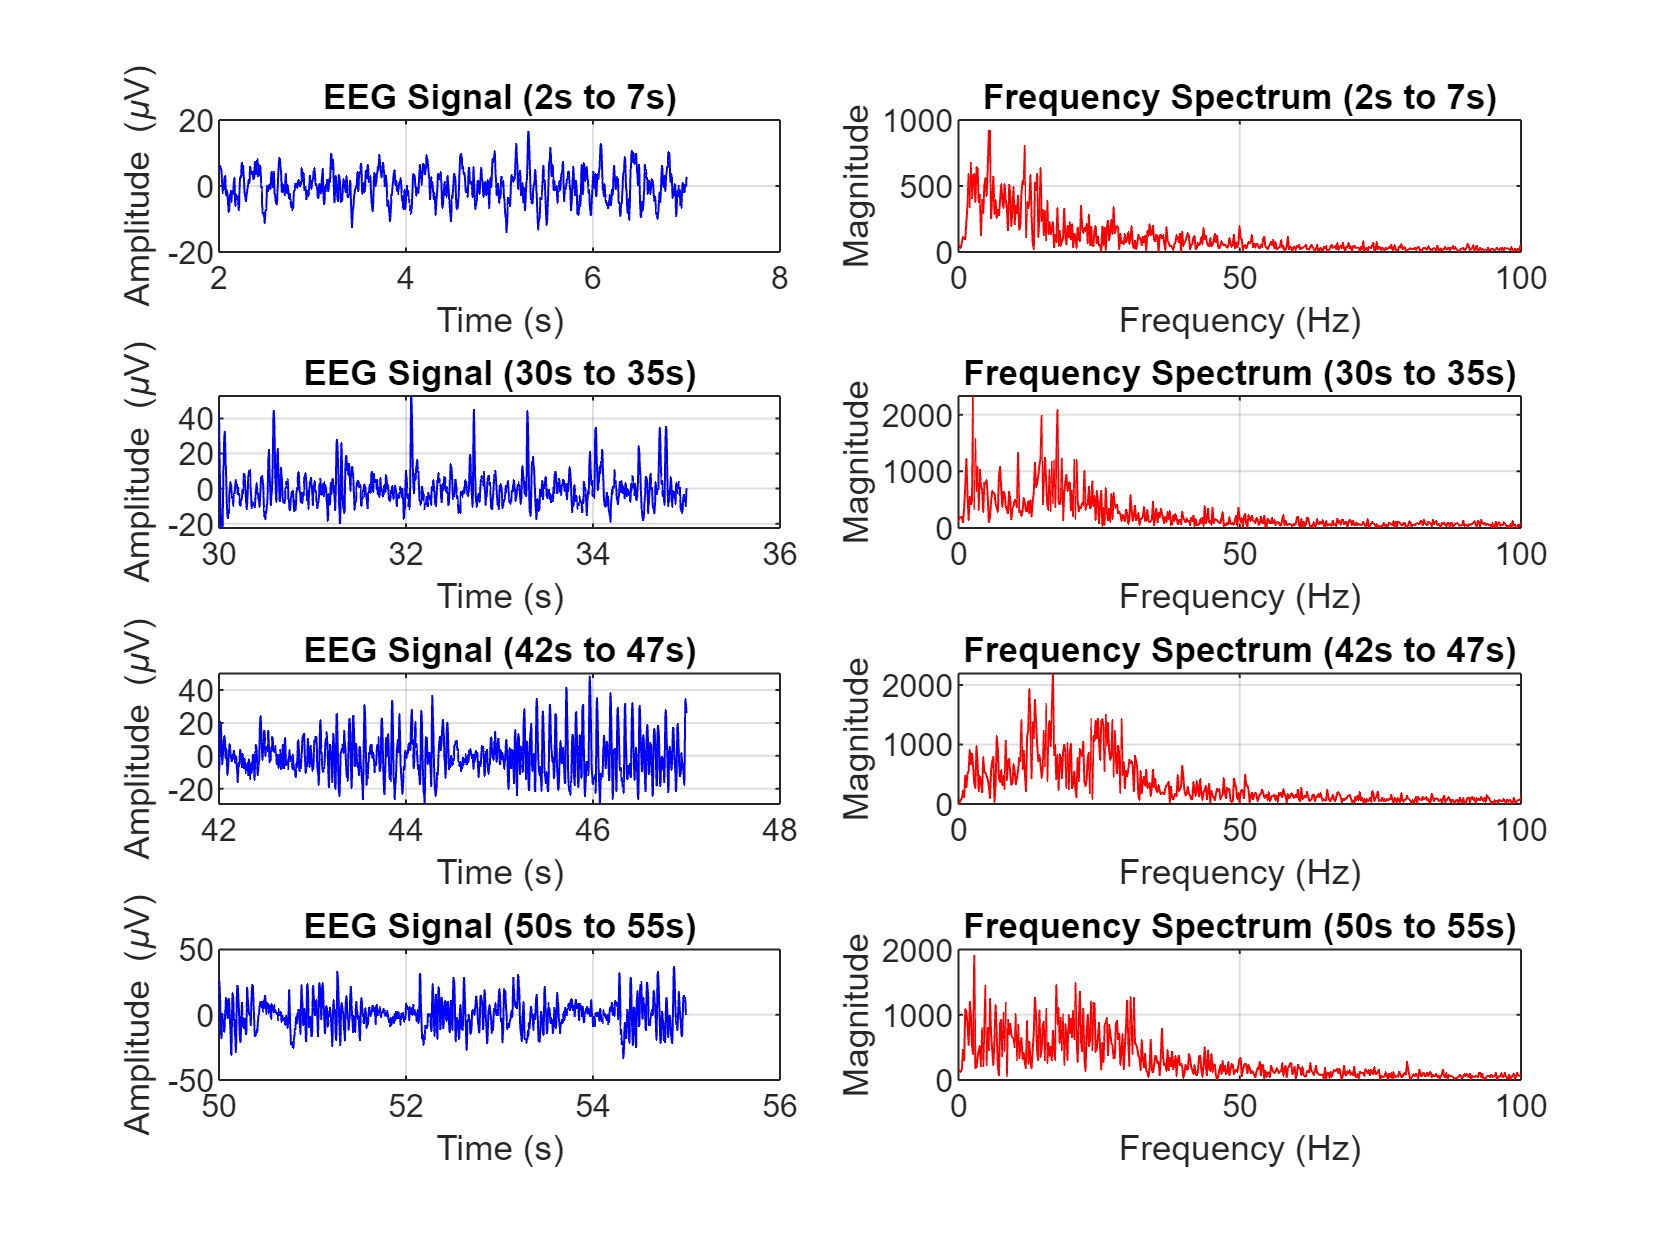

%% 

segments = [2 7;
           30 35;
           42 47; 
            50 55];

figure;
for i = 1:size(segments, 1)
    idx_start = find(time >= segments(i,1), 1);
    idx_end = find(time <= segments(i,2), 1, 'last');
    
    eeg_segment = ch5_data(idx_start:idx_end);


    time_segment = time(idx_start:idx_end);
    
    N = length(eeg_segment); 
    fft_signal = fft(eeg_segment); 
    freq = (0:N-1) * (fs/N); 
    fft_mag = abs(fft_signal(1:floor(N/2))); 
    freq2 = freq(1:floor(N/2)); 

    subplot(4, 2, (i-1)*2 + 1);
    plot(time_segment, eeg_segment, 'b');
    xlabel('Time (s)');
    ylabel('Amplitude (\muV)');
    title(['EEG Signal (', num2str(segments(i,1)), 's to ', num2str(segments(i,2)), 's)']);
    grid on;

    subplot(4, 2, (i-1)*2 + 2);
    plot(freq2, fft_mag, 'r');
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title(['Frequency Spectrum (', num2str(segments(i,1)), 's to ', num2str(segments(i,2)), 's)']);
    xlim([0 100]); 
    grid on;
end

**Q7:**

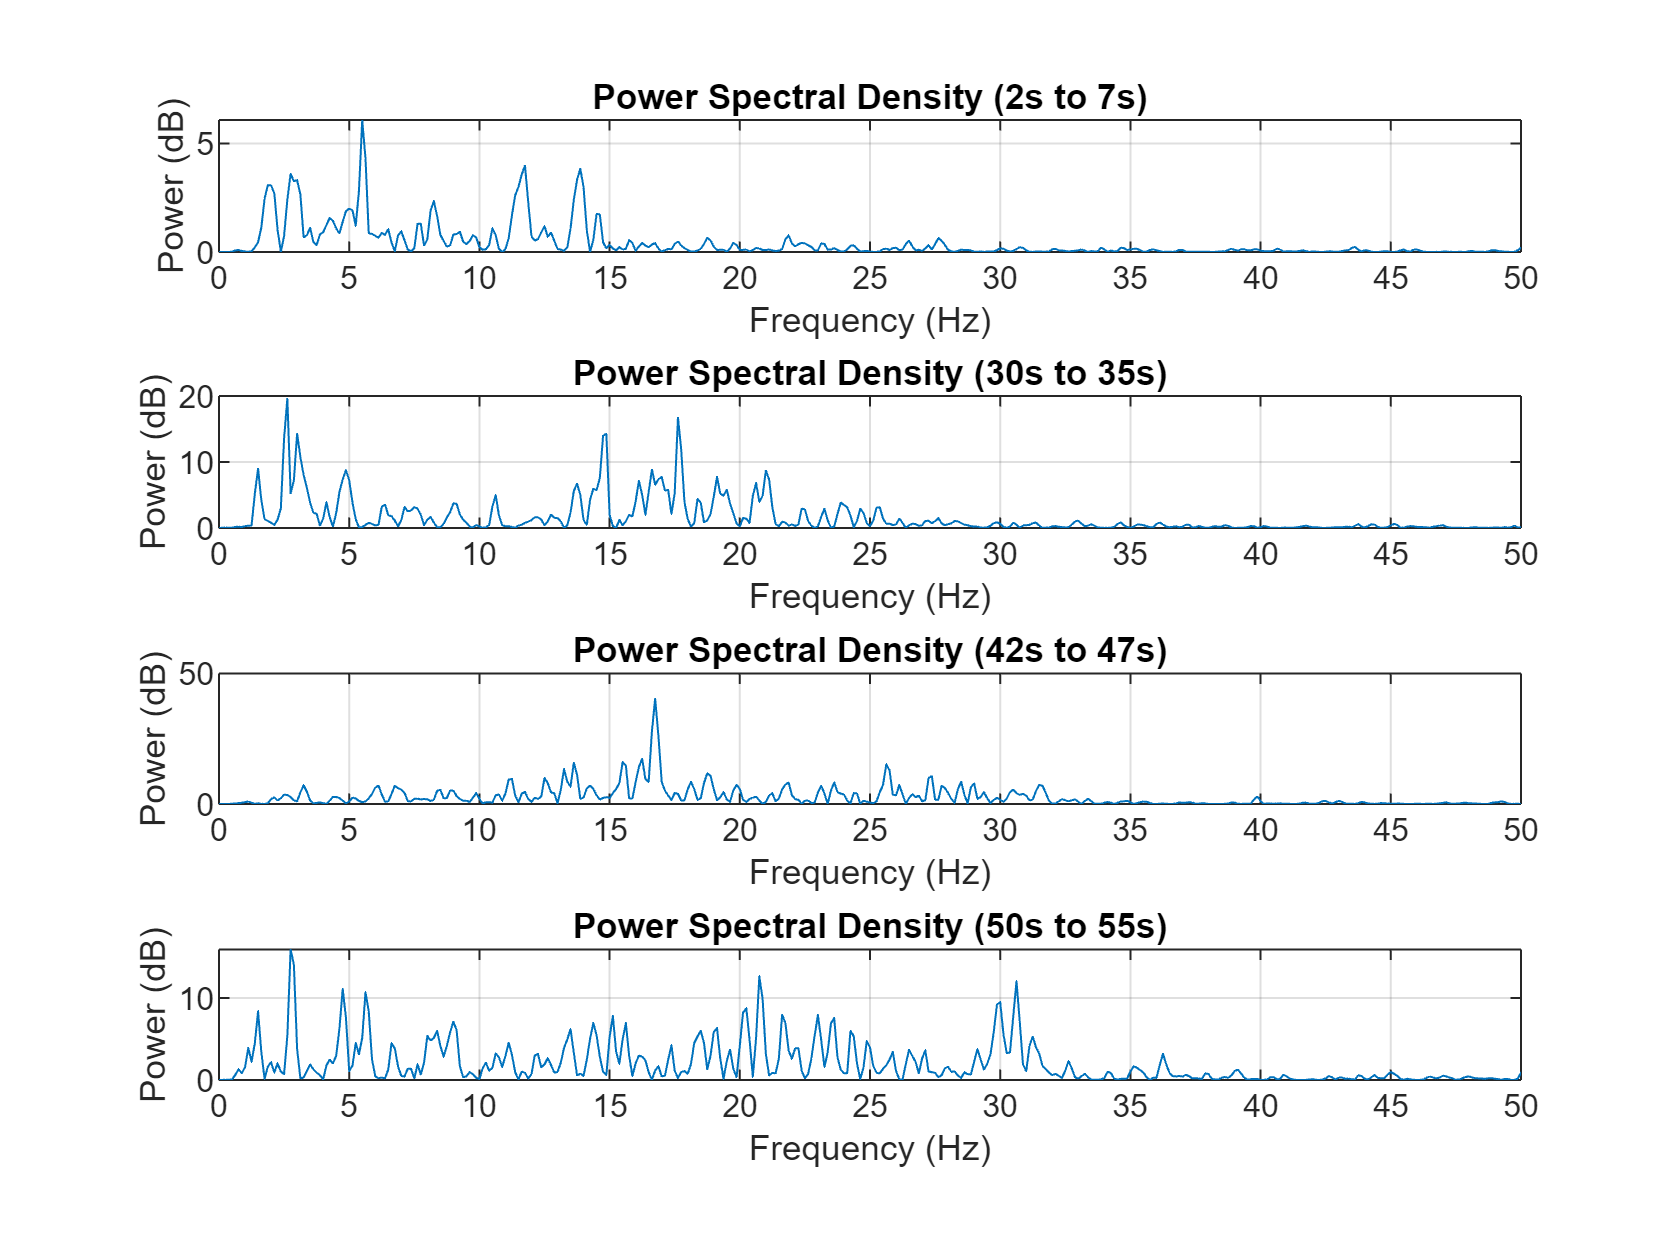

%%
 segments = [2 7;
     30 35;
     42 47;
     50 55];


 figure;

for i = 1:size(segments, 1)
    idx_start = find(time >= segments(i,1), 1);
    idx_end = find(time <= segments(i,2), 1, 'last');
    
    eeg_segment = ch5_data(idx_start:idx_end);
    
    [Pxx, Freq] = pwelch(eeg_segment, hamming(length(eeg_segment)), [], [], fs);
    
    subplot(4, 1, i);
    plot(Freq, (Pxx)); 
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    title(['Power Spectral Density (', num2str(segments(i,1)), 's to ', num2str(segments(i,2)), 's)']);
    xlim([0 50]); 
    grid on;
end

**Q8: why do we use hamming(for report)**

This sudden jump to zero creates artificial high frequencies that don't exist in your real signal. The FFT sees this sharp edge and thinks "Oh! There's a sudden change here!" and adds fake frequency components.  so we use hamming to smooth this sudden changes to get us the real fft.**so its neccesary to  use hamming in order to get proper  frequency spectrum**

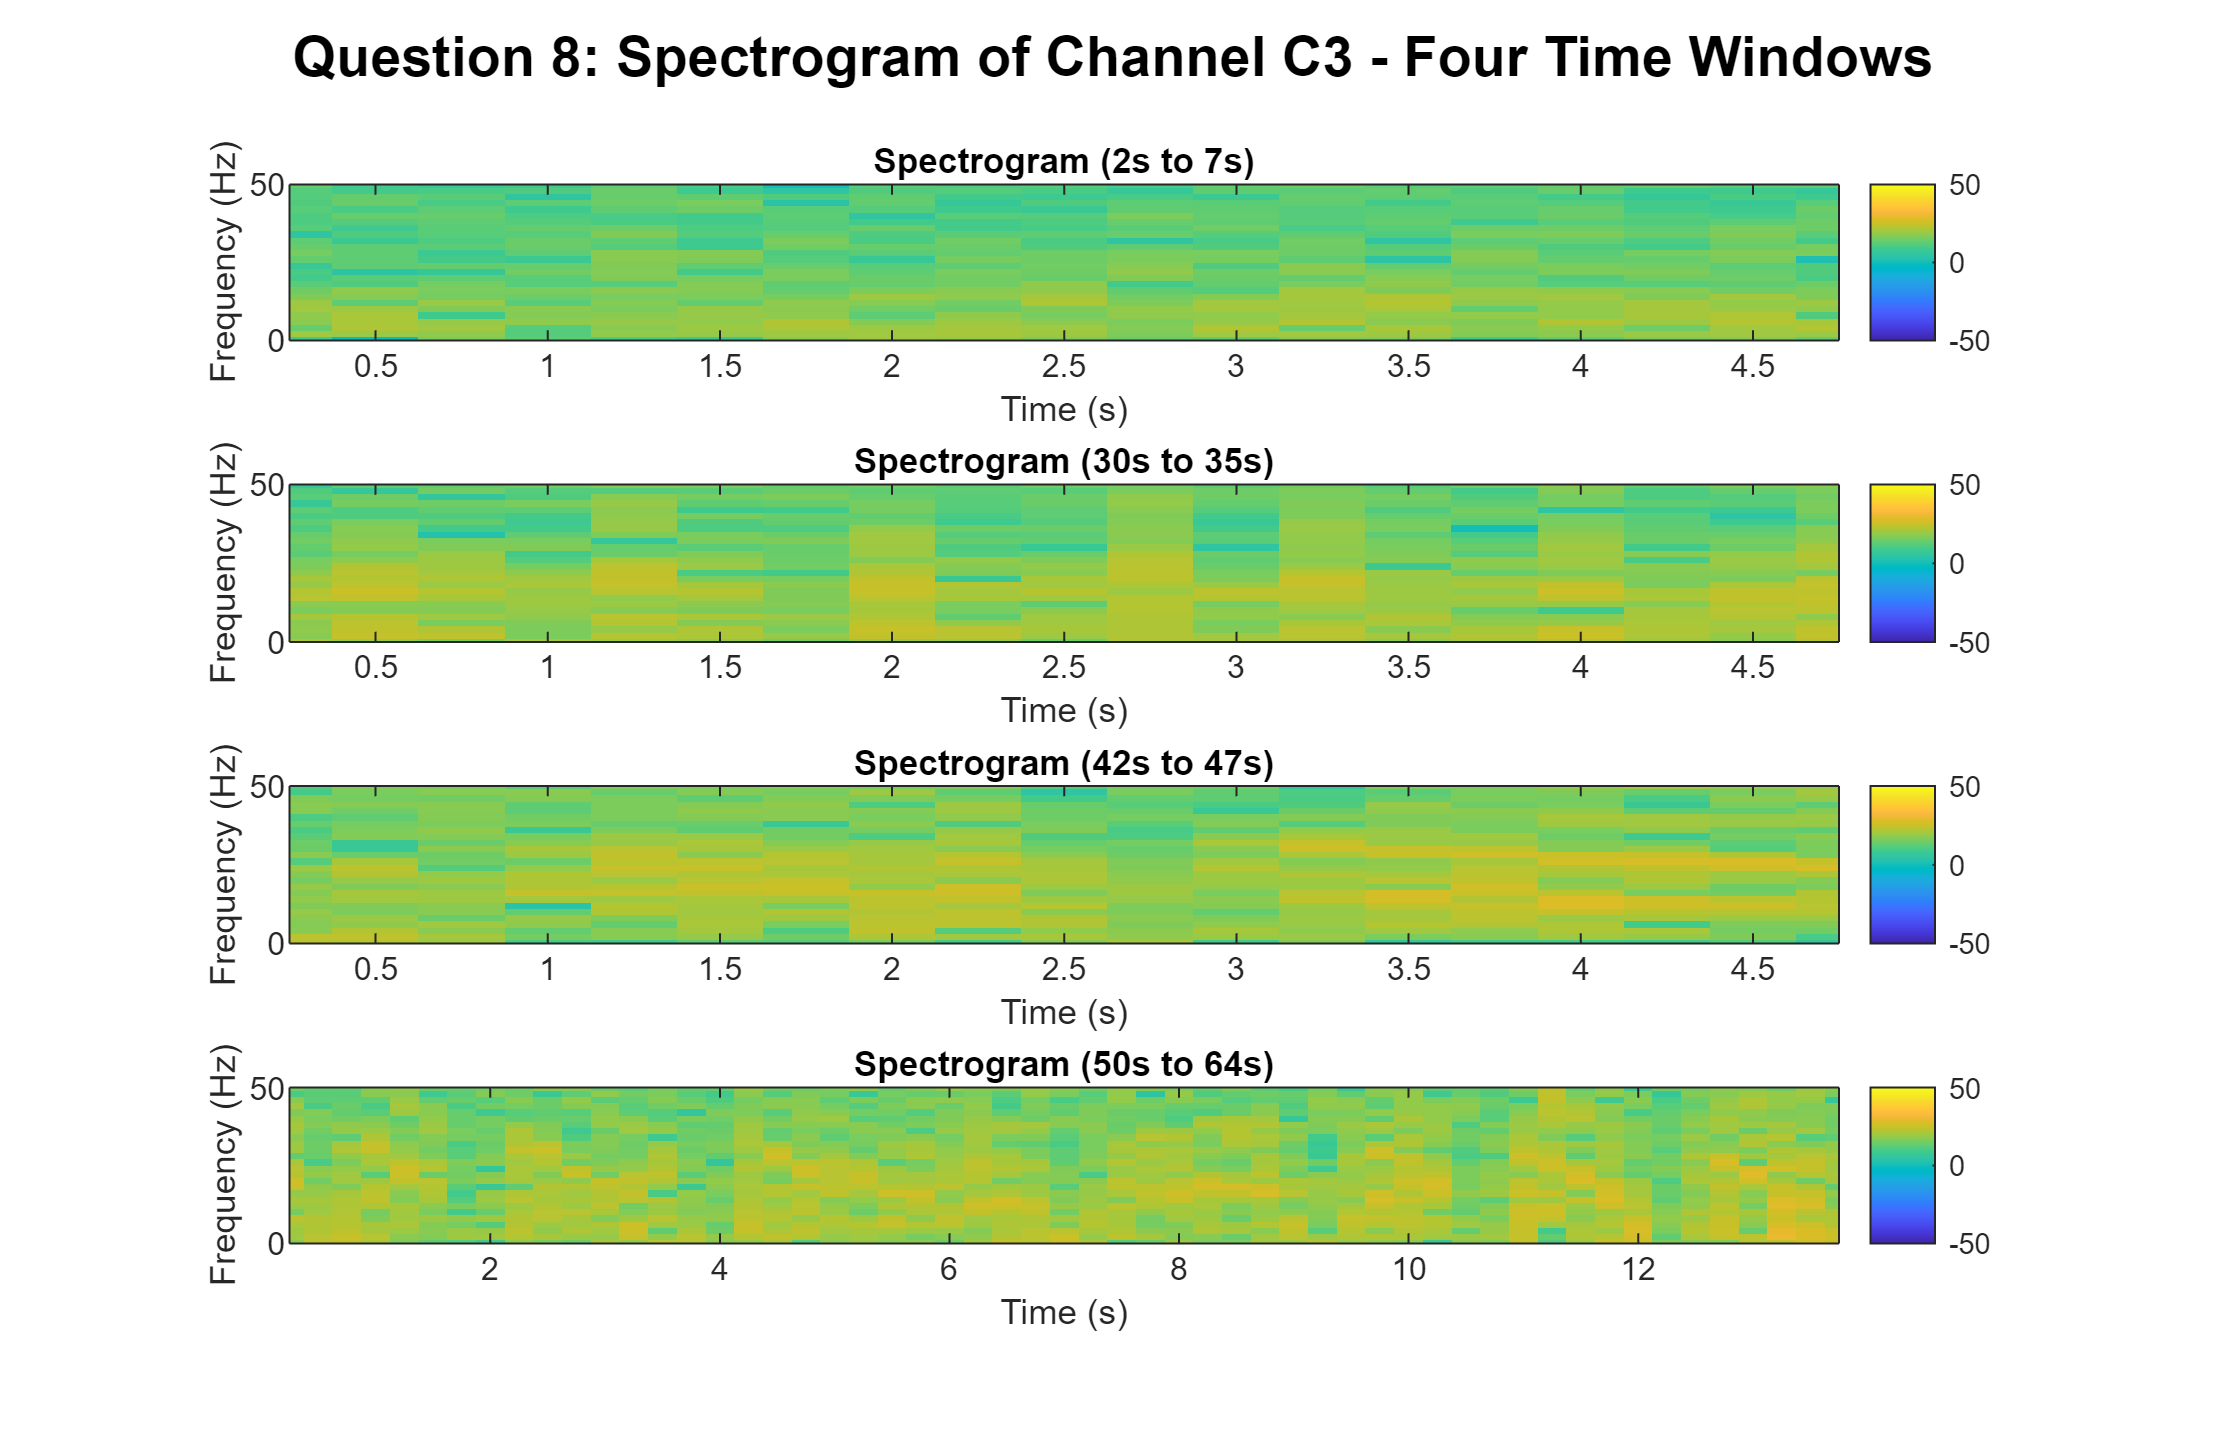


L = 128;           % window length
n_Overlap = 64;    % Overlap
n_fft = 128;       % FFT points
window = hamming(L);
total_time=length(ch5_data)/fs;
segments = [2, 7;
            30, 35;
            42, 47;
            50,64];

window_names = {'Baseline (2-7 sec)', 'Spikes (30-35 sec)', ...
                'Fast Activity (42-47 sec)', 'Slow Waves (50-55 sec)'};


figure('Position', [100, 100, 1400, 900]);

for i = 1:4
    t_start = segments(i, 1);
    t_end = segments(i, 2);
    
    % Convert times to sample indices
    sample_start = round(t_start * fs)+1;
    sample_end = round(t_end * fs);
    
    signal_segment = ch5_data(sample_start:sample_end); 
    [S, F, T] = spectrogram(signal_segment, window, n_Overlap, n_fft, fs); 
    subplot(4, 1, i);
  imagesc(T, F, 10*log10(abs(S))); % Convert to dB scale
 axis xy;
 xlabel('Time (s)');
 ylabel('Frequency (Hz)');
 title(['Spectrogram (', num2str(segments(i,1)), 's to ', num2str(segments(i,2)), 's)']);
 colorbar;
 caxis([-50 50]);
 % Best for EEG spectrograms:
 xlim([min(T) max(T)]);
  ylim([0 50]);
 
 end

sgtitle('Question 8: Spectrogram of Channel C3 - Four Time Windows', 'FontSize', 14, 'FontWeight', 'bold');

**Q9:**

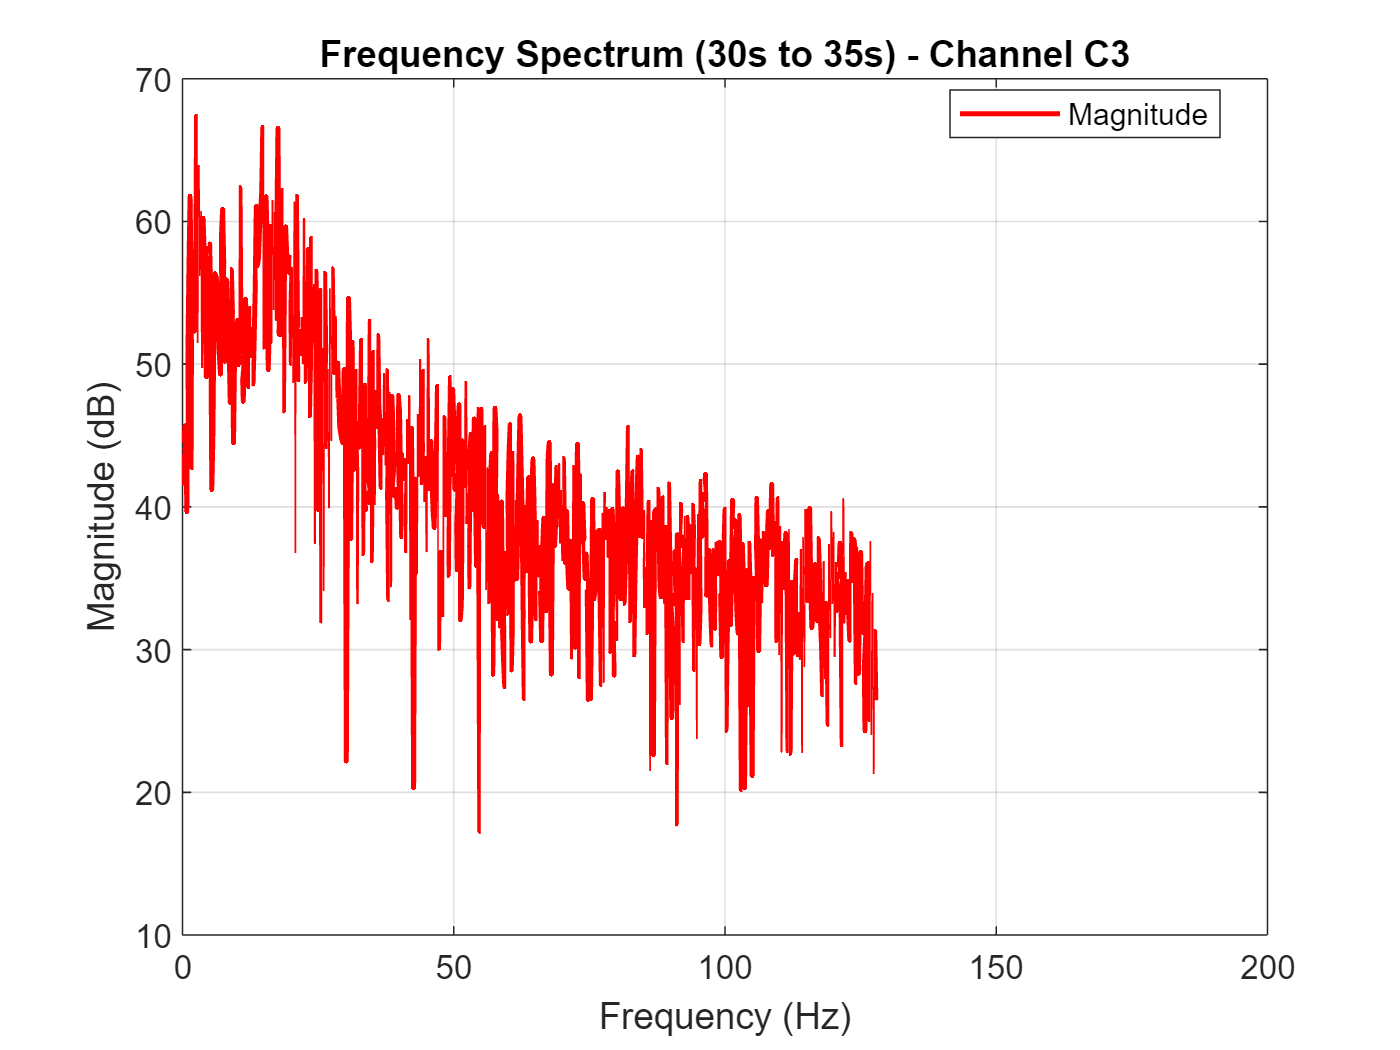

%% Extract the signal segment (30-35 seconds)
eeg_p2 = ch5_data(30*fs+1 : 35*fs);
N = length(eeg_p2);
fft_signal2 = fft(eeg_p2);
freq = (0:N-1) * (fs/N);
freq2 = freq(1:floor(N/2));


fft_mag_linear = abs(fft_signal2(1:floor(N/2)));
fft_mag_dB = 20 * log10(fft_mag_linear + eps); 

% Plot
figure;
plot(freq2, fft_mag_dB, 'r-', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title(sprintf('Frequency Spectrum (30s to 35s) - Channel C3'));
xlim([0 200]);
grid on;
legend('Magnitude', '-3 dB Point', 'Cutoff Frequency', 'Location', 'best');

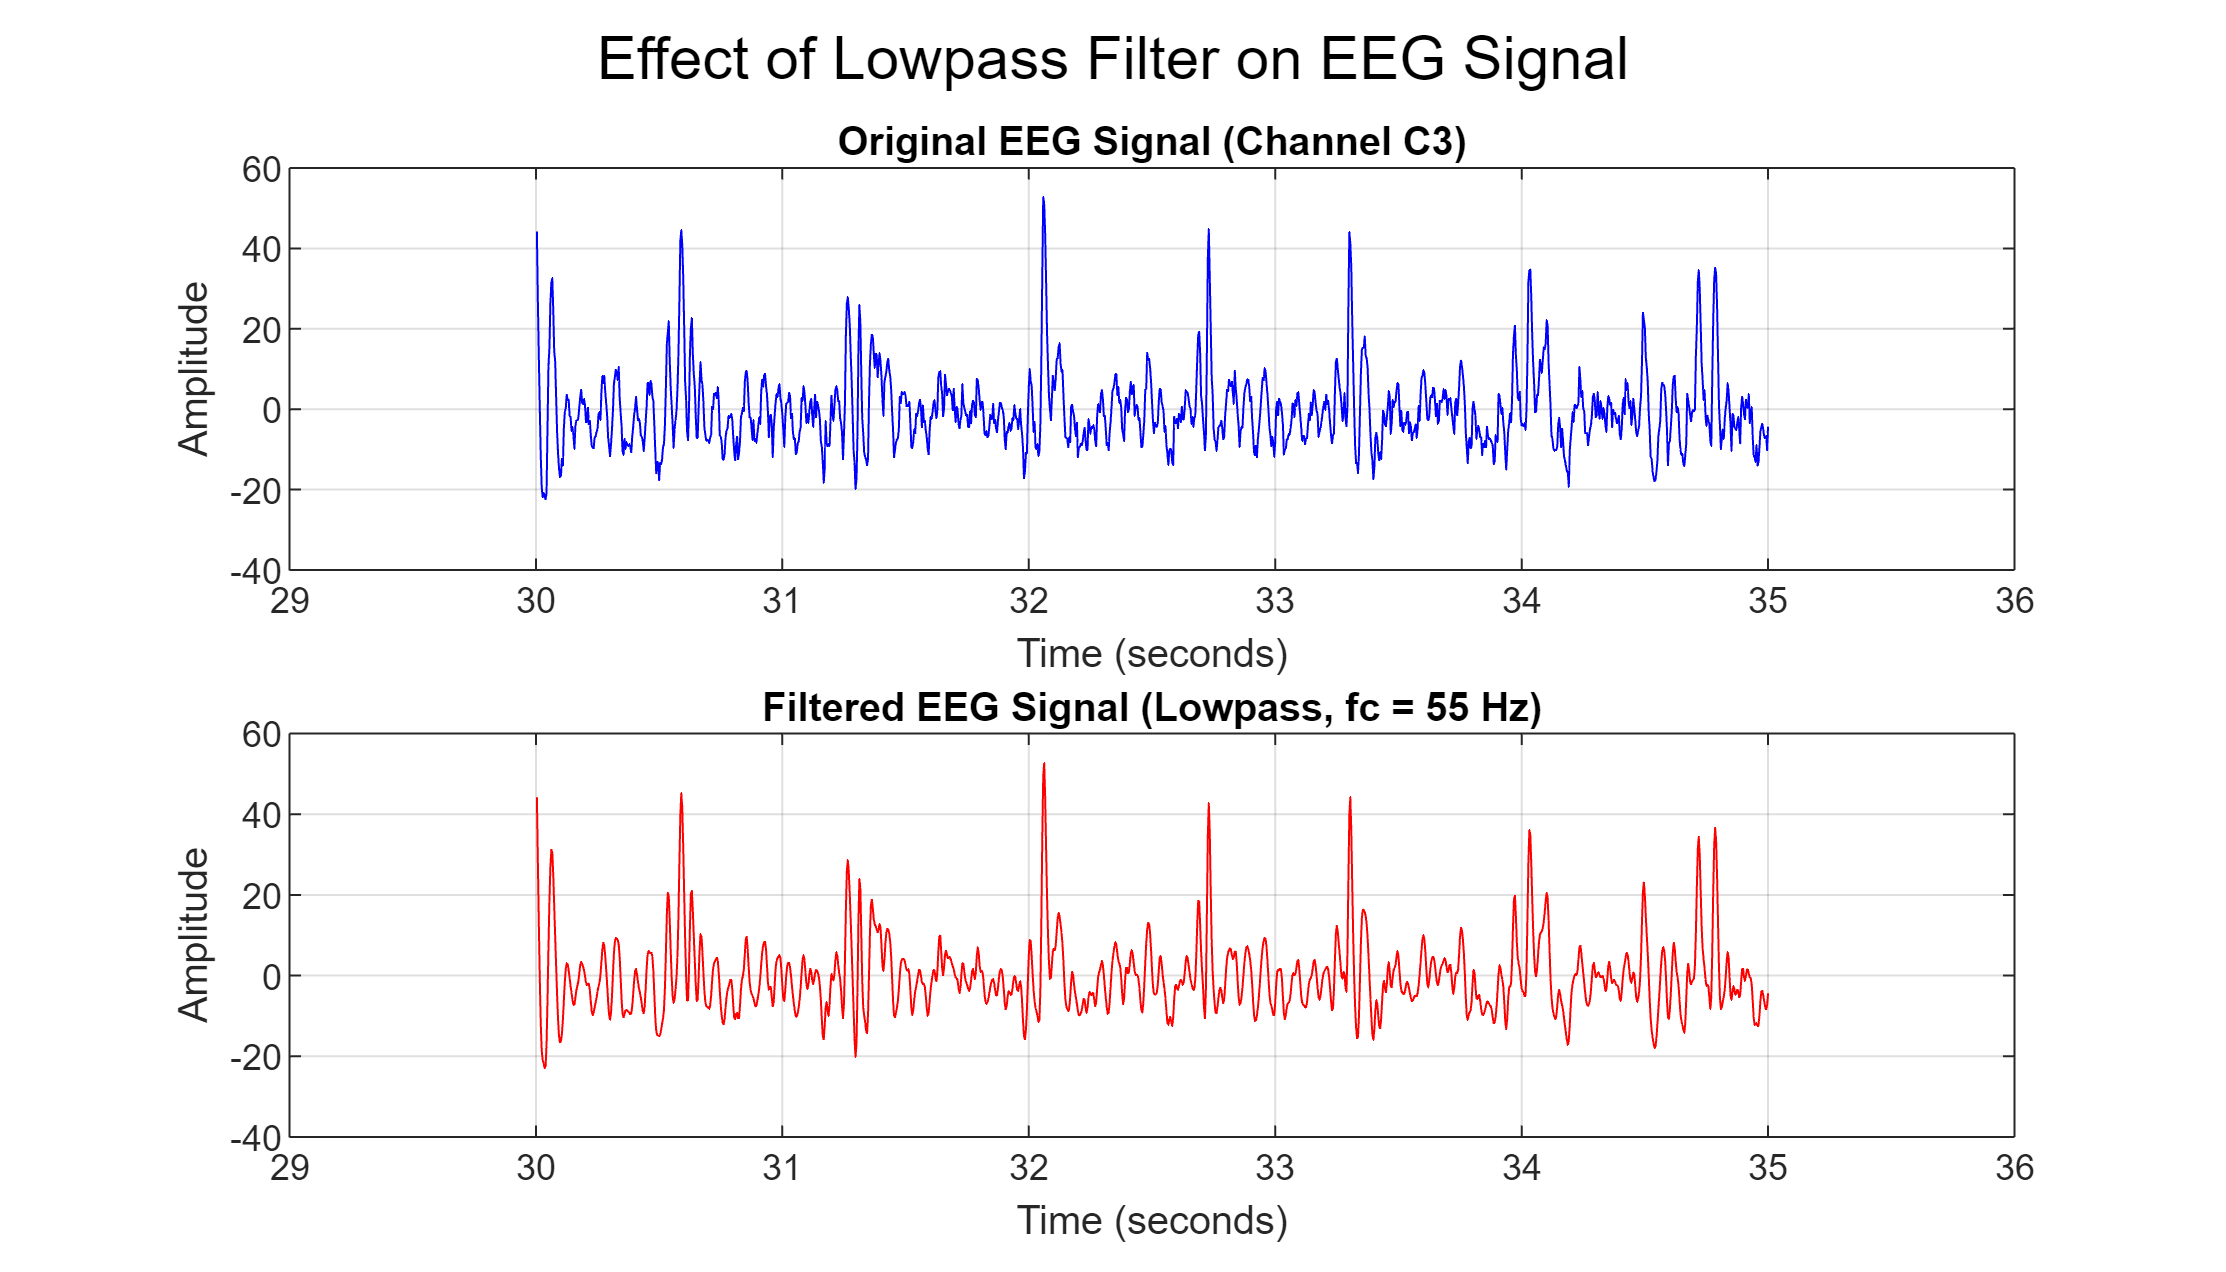

%% creating a lowpass filter for downsampling

fc = 40;         % Cutoff frequency 
order = 4;       % Filter order (4th order is common for EEG)
% Normalized cutoff frequency (Nyquist frequency = fs/2)
Wn = fc / (fs/2);  
[b, a] = butter(order, Wn, 'low');
% Filter the signal
ch5_p2=ch5_data(30*fs+1:35*fs);

ch5_data_filtered = filtfilt(b, a, ch5_p2);  % filtfilt = zero-phase filtering
time_p2 = (30*fs+1 : 35*fs) / fs;

% Plot original vs filtered signal
figure('Position', [100, 100, 1400, 800]);

subplot(2,1,1);
plot(time_p2, ch5_p2, 'b-', 'LineWidth', 0.5);
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Original EEG Signal (Channel C3)');
xlim([29,36]);
grid on;

subplot(2,1,2);
plot(time_p2, ch5_data_filtered, 'r-', 'LineWidth', 0.5);
xlabel('Time (seconds)');
ylabel('Amplitude');
title(sprintf('Filtered EEG Signal (Lowpass, fc = %d Hz)', fc));
xlim([29,36]);
grid on;

sgtitle('Effect of Lowpass Filter on EEG Signal');

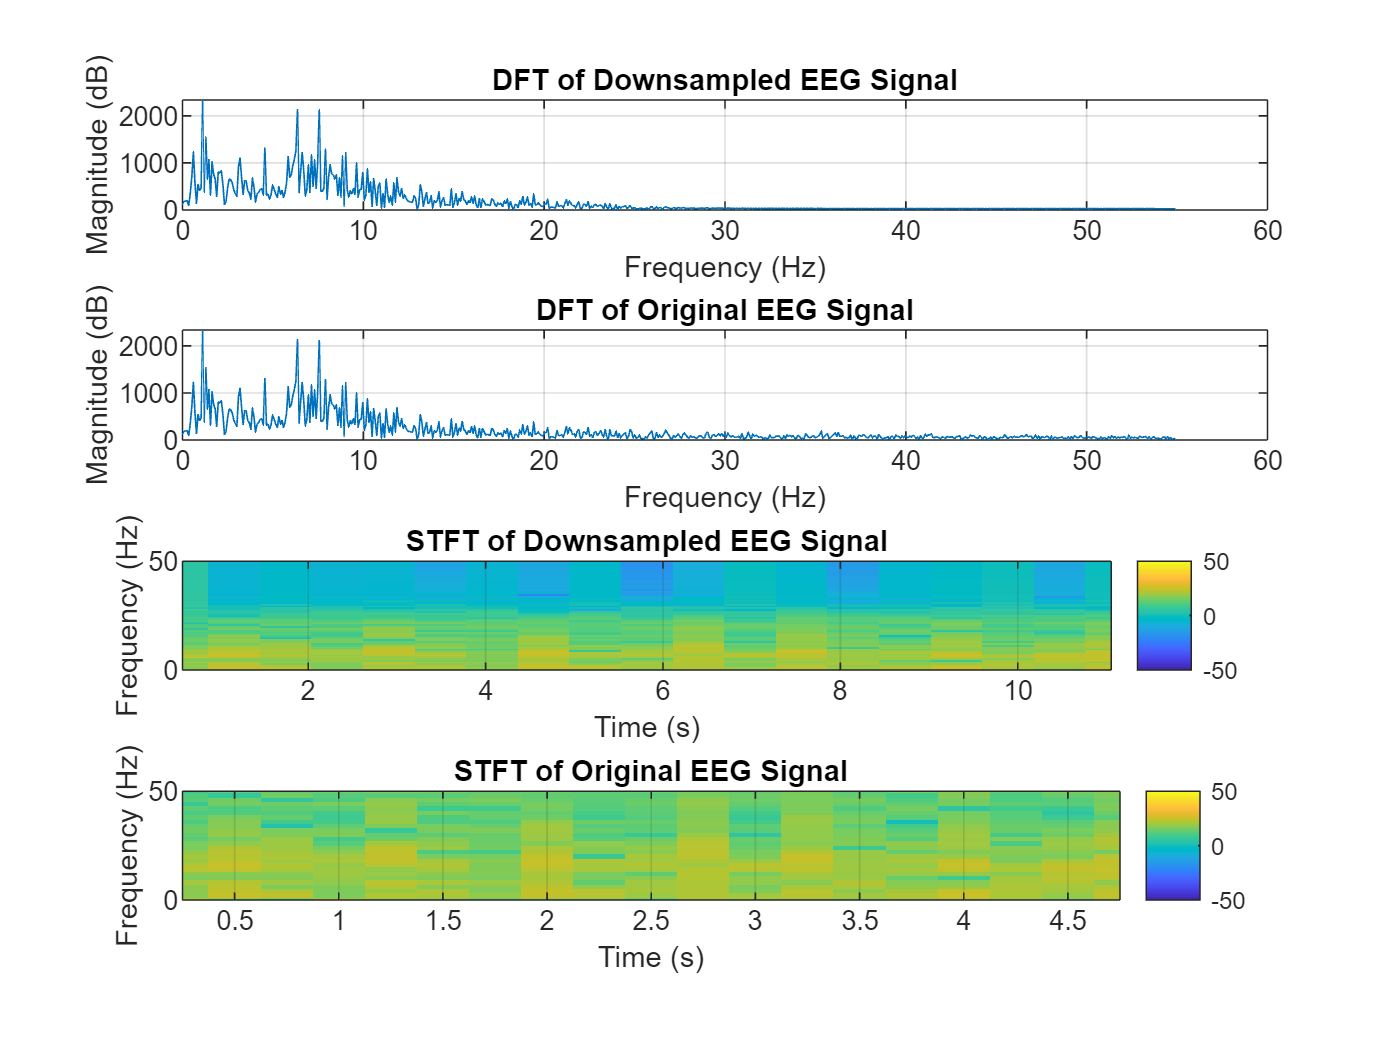

fft_signal3=fft(ch5_data_filtered);
N=length(fft_signal3);
freq = (0:N-1) * (2*fc/N);
freq3 = freq(1:floor(N/2));
fft_signal3_mag=abs(fft_signal3(1:floor(N/2)));

fft_original_signal=fft(ch5_p2);
N2=length(fft_original_signal);
freq = (0:N-1) * (fs/N);
freq2= freq(1:floor(N2/2));
fft_signal2_mag=abs(fft_original_signal(1:floor(N2/2)));

subplot(4,1,1);
plot(freq3,(20*log10(fft_signal3_mag+eps)));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('DFT of Downsampled EEG Signal');
grid on;
subplot(4,1,2);
plot(freq3,(20*log10(fft_signal2_mag+eps));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('DFT of Original EEG Signal');
grid on;

[S, F, T] = spectrogram(ch5_data_filtered, window, n_Overlap, n_fft,fc*2);
[S0,F0,T0]=spectrogram(ch5_p2, window, n_Overlap, n_fft, fs);

 subplot(4,1,3);
 imagesc(T, F, 10*log10(abs(S)));
axis xy;
 xlabel('Time (s)');
 ylabel('Frequency (Hz)');
 title('STFT of Downsampled EEG Signal');
 colorbar;
 caxis([-50 50]);
 xlim([min(T) max(T)]);
 ylim([0 50]);
 grid on;

 subplot(4,1,4);
 imagesc(T0, F0, 10*log10(abs(S0)));
 axis xy;
 xlabel('Time (s)');
 ylabel('Frequency (Hz)');
 title('STFT of Original EEG Signal');
 colorbar;
 caxis([-50 50]);
 xlim([min(T0) max(T0)]);
 ylim([0 50]);
 grid on;

function disp_eeg(Z, offset, feq, ElecName)
     [num_channels, num_samples] = size(Z);
      time = (0:num_samples-1) / feq;
    
    
    figure('Position', [100, 100, 1400, 800]);
    
    % Plot each channel with vertical offset
    hold on;
    
    for i = 1:num_channels
        % Apply offset
        % Subtract mean to center each channel around its offset level
        ch_data = Z(i, :) - mean(Z(i, :)) + (i-1) * offset;
        
        plot(time, ch_data, 'b-', 'LineWidth', 0.5);
        
        % Add channel label on the right side
        text(time(end) + 0.5, (i-1)*offset, ElecName{i}, ...
            'FontSize', 8, 'VerticalAlignment', 'middle');
    end
 
    xlabel('Time (seconds)', 'FontSize', 12);
    ylabel('Channel Number (with offset)', 'FontSize', 12);
    title('Multichannel EEG Recording', 'FontSize', 14);
    
    % Adjust y-axis limits to show all channels with some padding
    ylim([-offset, (num_channels) * offset]);
    
    % Adjust x-axis limits (add small margin for labels)
    xlim([0, time(end) + 2]);
    
    grid on;
    hold off;
    
    % Optional: Add horizontal lines separating channels
    for i = 0:num_channels
        line([0, time(end)], [i*offset, i*offset], ...
            'Color', [0.8 0.8 0.8], 'LineStyle', ':', 'LineWidth', 0.5);
    end
end 